close all 
clear all
clc

# Filtrowanie tla

I = importdata('example.jpg');

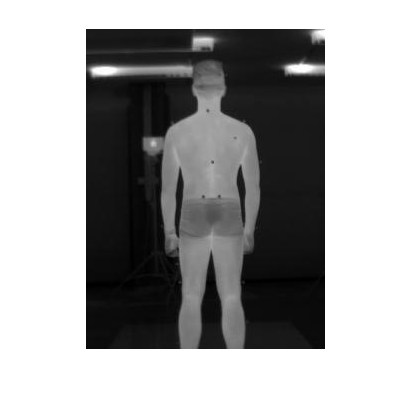

imshow(I);


grayI = rgb2gray(I);
imshow(grayI);

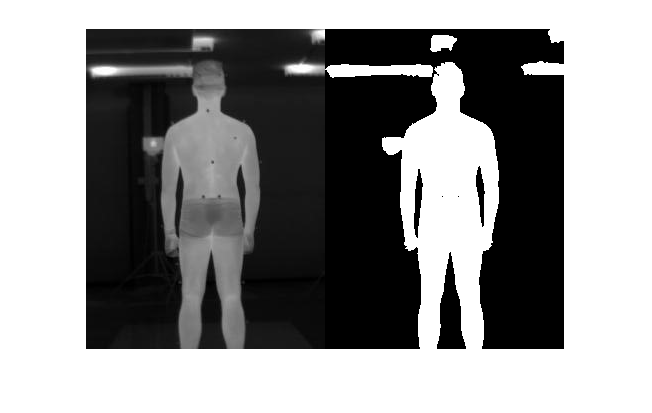


T = 0.30;
bw1 = imbinarize(grayI, T);
imshowpair(grayI, bw1,'montage')

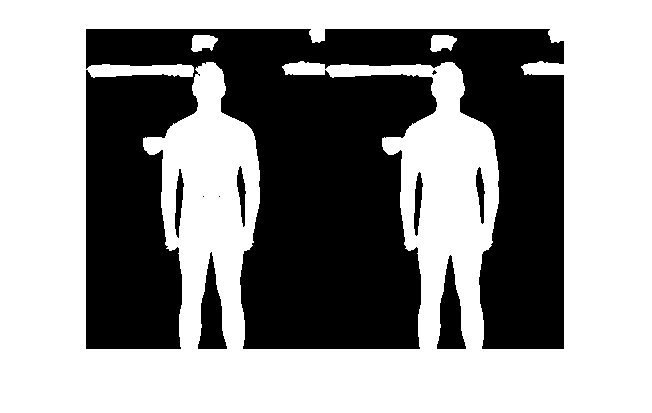


r = 1;
se = strel('disk', r);
bw2 = imclose(bw1,se);
imshowpair(bw1, bw2, 'montage')

Filtrowanie lamp

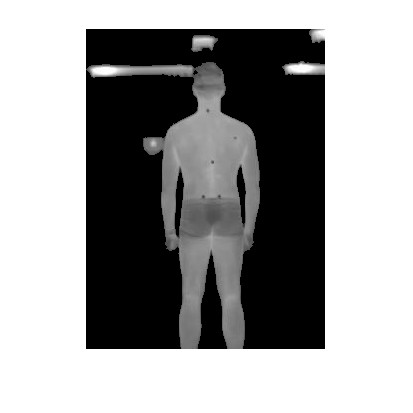

im2 = grayI.*uint8(bw2);
imshow(im2)

% r = 2;
% se = strel( 'disk',r);
% bw3 = imopen(bw2,se);
% imshowpair(bw1, bw3, 'montage')


% m = [30,10];
% se = strel( 'rectangle',m);
% bw3 = imclose(bw2,se);
% imshowpair(bw1, bw3, 'montage')

Pobranie punktow poczatkowych

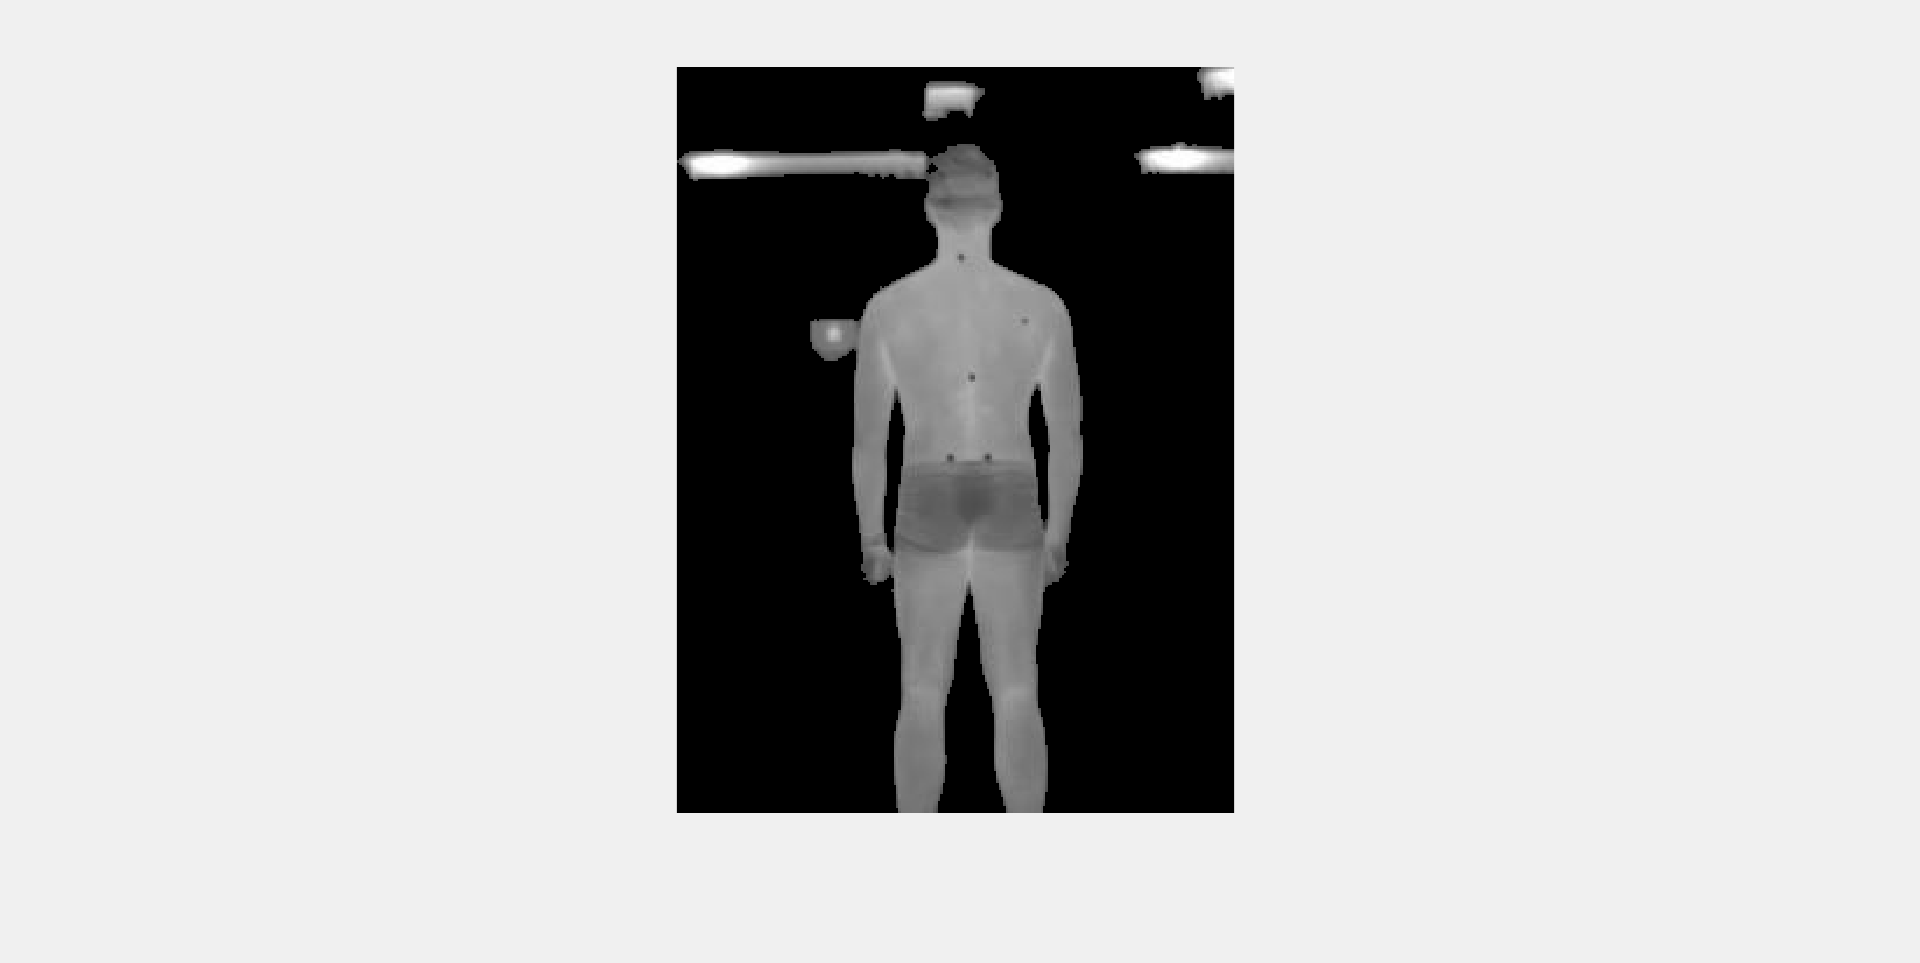

im2 = grayI.*uint8(bw2);
imshow(im2);

[x, y] = ginput(2);

x = round(x);
y = round(y);

Wyswietlanie wskazanych punktow

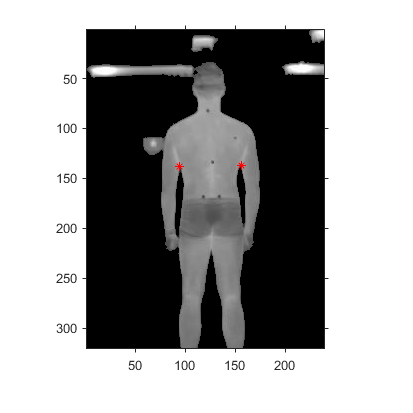

imshow(im2);
axis on
hold on;
plot(x(1), y(1), 'r*');
hold on;
plot(x(2), y(2), 'r*');

Wyszukiwanie gornych punktow plecow

row = find(im2(:,x(1)),1,'first');
col = x(1);

hold on;
plot(col, row, 'r*');

row2 = find(im2(:,x(2)),1,'first');
col2 = x(2);

hold on;
plot(col2, row2, 'r*');